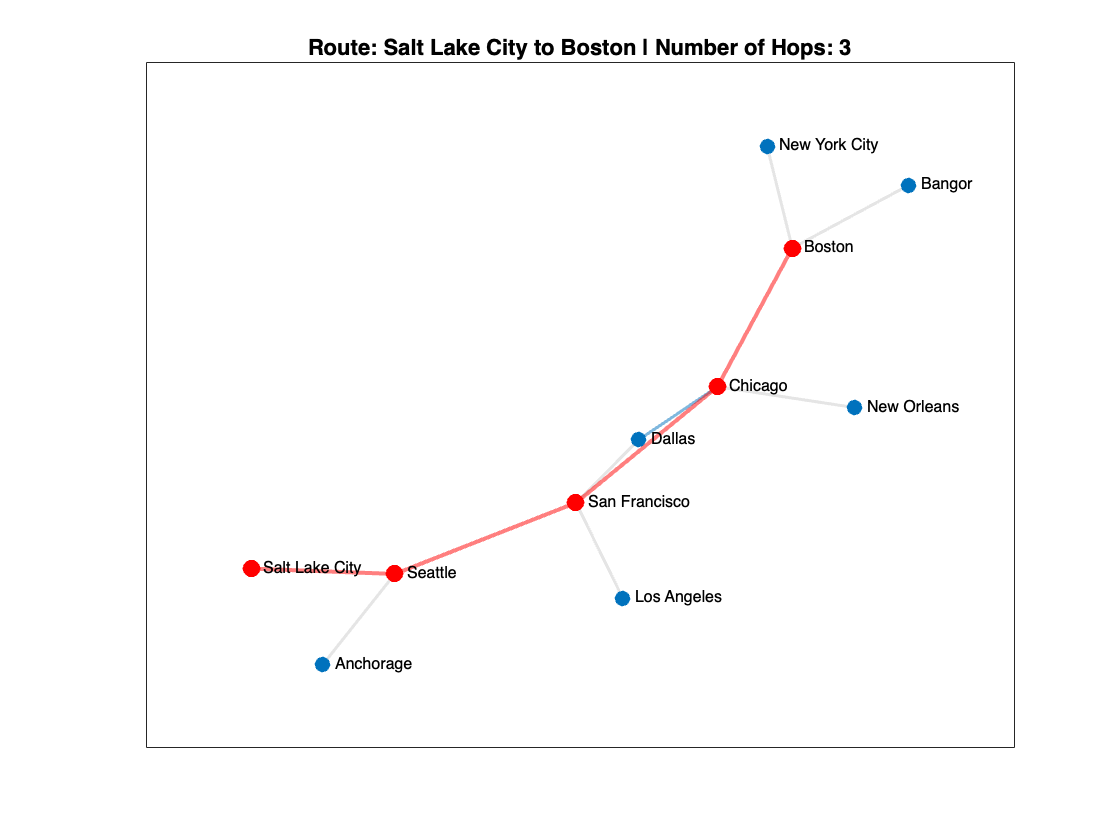

% Step 1: Define the adjacency matrix for the given network (symmetric version)
A = [0 1 0 0 0 0 0 0 0 0 0;
     1 0 1 1 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0;
     0 1 0 0 1 1 1 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 1 0 0 1 1 0 1 0;
     0 0 0 1 0 1 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 1 0 0 1 0 1;
     0 0 0 0 0 0 0 0 0 1 0];

% Ensure the matrix is symmetric (undirected graph)
A = A + A';

% Step 2: Create the graph
G = graph(A);

% Step 3: Define the node labels (city names)
nodeLabels = {'Anchorage', 'Seattle', 'Salt Lake City', 'San Francisco', ...
              'Los Angeles', 'Chicago', 'Dallas', 'New Orleans', ...
              'New York City', 'Boston', 'Bangor'};

% Step 4: Calculate the number of hops between each pair of cities
numNodes = numnodes(G);
numHops = zeros(numNodes, numNodes); % Initialize matrix to store number of hops
paths = cell(numNodes, numNodes);    % Cell array to store paths

for i = 1:numNodes
    for j = 1:numNodes
        if i ~= j
            [P, ~] = shortestpath(G, i, j); % Find shortest path between nodes i and j
            numHops(i, j) = length(P) - 2;  % Number of hops is the number of intermediate nodes
            paths{i, j} = P;                % Store the path for animation
        else
            numHops(i, j) = 0;              % No hops needed if origin and destination are the same
            paths{i, j} = i;                % Path is just the node itself
        end
    end
end

% Step 5: Animate the paths on the graph
figure;
h = plot(G, 'NodeLabel', nodeLabels, 'LineWidth', 1.5, 'MarkerSize', 7);
title('Animated Paths Showing Number of Hops');
highlight(h, 'Edges', [], 'EdgeColor', [0.8 0.8 0.8]); % Set default edge color

% Set up colormap for highlighting
colors = lines(numNodes);

for i = 1:numNodes
    for j = 1:numNodes
        if i ~= j
            % Highlight the path from node i to node j
            pathNodes = paths{i, j};
            % Highlight nodes along the path
            highlight(h, pathNodes, 'NodeColor', 'red', 'MarkerSize', 8);
            % Highlight edges along the path
            pathEdges = [];
            for k = 1:length(pathNodes)-1
                edgeIndex = findedge(G, pathNodes(k), pathNodes(k+1));
                pathEdges = [pathEdges, edgeIndex];
            end
            highlight(h, 'Edges', pathEdges, 'EdgeColor', 'red', 'LineWidth', 2);
            % Update title to show the current path and number of hops
            currentRoute = [nodeLabels{i}, ' to ', nodeLabels{j}];
            currentHops = numHops(i, j);
            title(['Route: ', currentRoute, ' | Number of Hops: ', num2str(currentHops)]);
            drawnow;
            pause(1); % Pause for a second to visualize
            % Reset the colors back to default for next iteration
            highlight(h, pathNodes, 'NodeColor', [0 0.4470 0.7410], 'MarkerSize', 7);
            highlight(h, 'Edges', pathEdges, 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1.5);
        end
    end
end


% Optional: Display the number of hops in a table format
cityPairs = {};
hopsList = [];
for i = 1:numNodes
    for j = 1:numNodes
        if i ~= j
            cityPairs = [cityPairs; [nodeLabels{i}, ' to ', nodeLabels{j}]];
            hopsList = [hopsList; numHops(i, j)];
        end
    end
end

T = table(cityPairs, hopsList, 'VariableNames', {'Route', 'NumberOfHops'});
disp('Number of Hops Between Each Pair of Cities:');

Number of Hops Between Each Pair of Cities:


disp(T);r

                   Route                   NumberOfHops
    ___________________________________    ____________

    {'Anchorage to Seattle'           }         0      
    {'Anchorage to Salt Lake City'    }         1      
    {'Anchorage to San Francisco'     }         1      
    {'Anchorage to Los Angeles'       }         2      
    {'Anchorage to Chicago'           }         2      
    {'Anchorage to Dallas'            }         2      
    {'Anchorage to New Orleans'       }         3      
    {'Anchorage to New York City'     }         4      
    {'Anchorage to Boston'            }         3      
    {'Anchorage to Bangor'            }         4      
    {'Seattle to Anchorage'           }         0      
    {'Seattle to Salt Lake City'      }         0      
    {'Seattle to San Francisco'       }         0      
    {'Seattle to Los Angeles'         }         1      
    {'Seattle to Chicago'          